clear
clc

t = 5;                         % Acquire data for 10 seconds
filename = 'lptdc_debug_data_hpch0_dpch20_norst_10k_3rd';      % Data file name 17:00
filename = 'lptdc_debug_data_hpch0_dpch20_norst_10k_4th';      % Data file name 17:04
filename = 'lptdc_debug_data_hpch0_dpch20_norst_10k_5th';      % Data file name 17:14
filename = 'lptdc_debug_data_hpch0_dpch20_norst_10k_6th';      % Data file name 17:54  change with no reason
filename = 'lptdc_debug_data_hpch0_dpch20_norst_10k_7th';      % Data file name 18:14
filename = 'lptdc_debug_data_hpch0_dpch20_norst_10k_8th';      % Data file name 18:23
filename = 'lptdc_debug_data_hpch0_dpch20_norst_10k_9th';      % Data file name 18:26
filename = 'lptdc_debug_data_hpch0_dpch20_norst_10k_10th';      % Data file name 18:38
filename = 'lptdc_debug_data_hpch0_dpch20_norst_10k_11th';      % Data file name 18:38
filename = ['..\..\..\..\data_WearableSystem\16module_Source_20180912\16module_Source_' int2str(201)];
% filename = '..\..\..\data_WearableSystem\16module_Source_20180709\16module_Source_1'
pvolt = 2500;    % Analog Positive Voltage +2.500V
nvolt = 500;     % Analog Negative Voltage -0.500V
svolt = 28000;   % SiPM Bias Voaltage +28.000V

sipm_power_ctl_port = 'COM4';
analog_positive_power_ctl_port = 'COM5';
analog_negative_power_ctl_port = 'COM6';

set_power = 0;     % 这个跟你没有关系，等于0就好
data_acq = 1;      % 如果只是分析数据，可以把这个置0,不重新采集数据
init_one_node = 0; % 初始化第一块节点类型，只想用第一块板子的时候把这个置为1，不能跟init_all_node同时为1
init_all_node = 1; % 初始化所有板子节点类型，想用多块板子的时候把这个置为1， 不能跟init_one_node同时为1

if set_power == 1 
    % Set dcpower as remote control mode
    dcpower_set_as_remote_mode(analog_positive_power_ctl_port);
    dcpower_set_as_remote_mode(analog_negative_power_ctl_port);
    dcpower_set_as_remote_mode(sipm_power_ctl_port);
    
    % Set analog positive voltage
    dcpower_set_votage(analog_positive_power_ctl_port, pvolt);    % +2.5V
    
    % Set analog negative voltage
    dcpower_set_votage(analog_negative_power_ctl_port, nvolt);     % -0.5V
    
    % Set SiPM bias voaltage
    dcpower_set_votage(sipm_power_ctl_port, svolt);              % +28.0V
end

if set_power == 1 
    dcpower_set_output_on(analog_positive_power_ctl_port);
    dcpower_set_output_on(analog_negative_power_ctl_port);
    dcpower_set_output_on(sipm_power_ctl_port);
end

if data_acq == 1
%     op = '..\PiModule\host\sw\dist\picopet\picopet.exe';
    op = '..\sw\dist\picopet\picopet.exe';
    trgt = '0x0000';
    
    %pin
    system([op ' -c 0x0001 ' trgt ' 0x00000000']);
    system([op ' -c 0x0001 ' trgt ' 0x00000000']);
    system([op ' -c 0x0001 ' trgt ' 0x00000000']);
    system([op ' -c 0x0001 ' trgt ' 0x00000000']);
    system([op ' -c 0x0001 ' trgt ' 0x00000000']);
    
        if init_one_node == 1
            % Node ID: 0x00 Node Type: 0x00
            system([op ' -c 0x0002 ' trgt ' 0x00000100']);
        end
        
        % 下面这段是初始化所有节点的，可能有bug,因为python程序还没完全开发好
        % 在1,2两条命令后加足够长的延时应该可以工作，不行就增大延时
        if init_all_node == 1
            trgt = '0xC000';
            system([op ' -c 0x0002 ' trgt ' 0x00000000']);    % 1
            pause(20);
            % 这里需要延时10s 你查下matlab的延时函数，我忘记了
            trgt = '0x000f'; % 假设有4块板子级联，这里就写3，有8块就写7
            system([op ' -c 0x0002 ' trgt ' 0x0000020f']);    % 2
            pause(5);
            % 延时2s
            % pin最后一块板子，pin成功代表初始化成功
            system([op ' -c 0x0001 ' trgt ' 0x00000000']);
            system([op ' -c 0x0001 ' trgt ' 0x00000000']);
            system([op ' -c 0x0001 ' trgt ' 0x00000000']);
            system([op ' -c 0x0001 ' trgt ' 0x00000000']);
            system([op ' -c 0x0001 ' trgt ' 0x00000000']);
        end
        
    % 开始采集
    system([op ' -a ' num2str(t) ' -o ' filename '.dat']);
end

2018-11-30 15:00:46,321 INFO [S] 0x0001 0x0000 0x00000000 
2018-11-30 15:00:46,522 INFO [R] 0x8001 0x0000 0x00000000 


2018-11-30 15:00:46,831 INFO [S] 0x0001 0x0000 0x00000000 
2018-11-30 15:00:47,032 INFO [R] 0x8001 0x0000 0x00000000 


2018-11-30 15:00:47,332 INFO [S] 0x0001 0x0000 0x00000000 
2018-11-30 15:00:47,532 INFO [R] 0x8001 0x0000 0x00000000 


2018-11-30 15:00:47,842 INFO [S] 0x0001 0x0000 0x00000000 
2018-11-30 15:00:48,043 INFO [R] 0x8001 0x0000 0x00000000 


2018-11-30 15:00:48,345 INFO [S] 0x0001 0x0000 0x00000000 
2018-11-30 15:00:48,545 INFO [R] 0x8001 0x0000 0x00000000 


2018-11-30 15:00:48,861 INFO [S] 0x0002 0xC000 0x00000000 
2018-11-30 15:00:52,871 WARNING Controller Unit is not responding. Try again or restart. 
2018-11-30 15:00:52,871 ERROR Response received does not match what I expected! Is it stuck? 
2018-11-30 15:00:52,871 INFO [R] 0x3F01 0x000F 0x00000002 


2018-11-30 15:01:13,262 INFO [S] 0x0002 0x000F 0x0000020F 
2018-11-30 15:01:13,663 INFO [R] 0x8002 0x000F 0x0000020F 


2018-11-30 15:01:18,947 INFO [S] 0x0001 0x000F 0x00000000 
2018-11-30 15:01:19,348 INFO [R] 0x8001 0x000F 0x00000000 


2018-11-30 15:01:19,653 INFO [S] 0x0001 0x000F 0x00000000 
2018-11-30 15:01:20,053 INFO [R] 0x8001 0x000F 0x00000000 


2018-11-30 15:01:20,361 INFO [S] 0x0001 0x000F 0x00000000 
2018-11-30 15:01:20,763 INFO [R] 0x8001 0x000F 0x00000000 


2018-11-30 15:01:21,055 INFO [S] 0x0001 0x000F 0x00000000 
2018-11-30 15:01:21,457 INFO [R] 0x8001 0x000F 0x00000000 


2018-11-30 15:01:21,776 INFO [S] 0x0001 0x000F 0x00000000 
2018-11-30 15:01:22,178 INFO [R] 0x8001 0x000F 0x00000000 


2018-11-30 15:01:22,470 ERROR [..\..\..\..\data_WearableSystem\16module_Source_20180912\16module_Source_201.dat] already exists! Choose another file name and try again. 


if set_power == 1 
    
    dcpower_set_output_off(sipm_power_ctl_port);
    dcpower_set_output_off(analog_negative_power_ctl_port);
    dcpower_set_output_off(analog_positive_power_ctl_port);
end

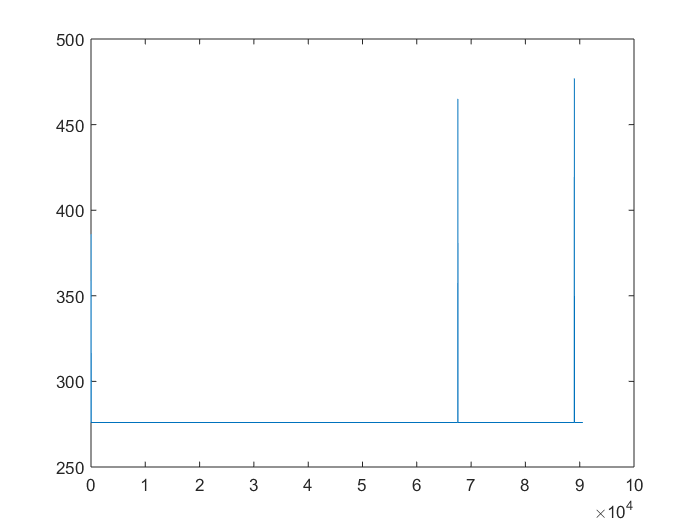

fid=fopen([filename '.dat'],'rb');
% fid=fopen(['.\data\' filename '.dat'],'rb');
raw = fread(fid,'uint8');
fclose(fid);
raw = raw(4001:end);
data = reshape(raw,4,length(raw)/4)';
% data = data(1:100000,:);
train_head_8bit = 254;
train_end_8bit = 253;
p1 = find(data(:,4) == train_head_8bit);
p2 = p1 + 1;
if  max(p2) > length(data)
    p2 = p2(1:end - 1);
end
train_head_index = p2((data(p2,4) == train_head_8bit) & (data(p2,1) == 0) & (data(p2,2) == 0) &(data(p2,3) == 0));  %%可能会受到TDC的高位计数为254的影响
% train_head_index = p2(data(p2,4) == train_head_8bit);  %%可能会受到TDC的高位计数为254的影响
train_cnt = length(train_head_index);
train_len = diff(train_head_index);
figure;plot(train_len);

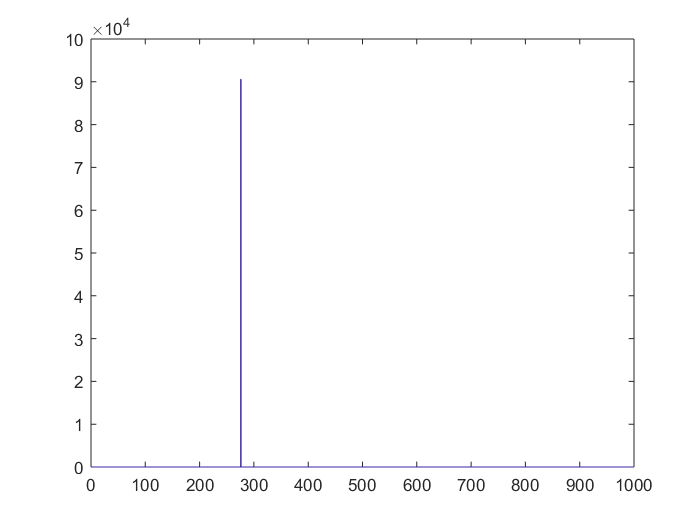

figure;hist(train_len,0:1:1000);xlim([0 1000]);

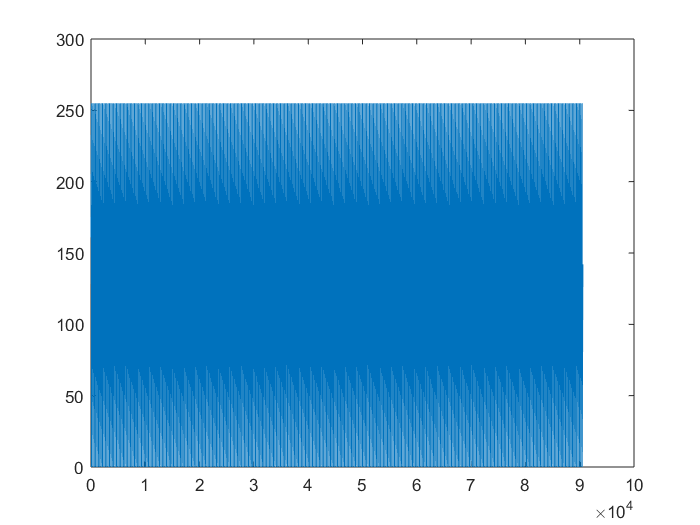

A2=unique(train_len);
n=histc(train_len,A2);
n1=[A2,n];
train_num = data(train_head_index - 1, 2);
figure;plot(train_num);

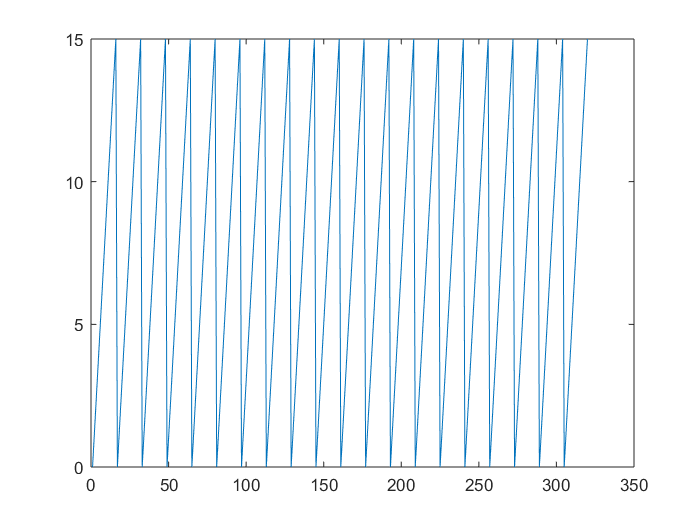

c_train_len = 276;
p1 = find(train_len == c_train_len);
complet_train_head_index = train_head_index(p1) - 1;

complet_train_cnt = length(complet_train_head_index);

train_data = zeros(complet_train_cnt * c_train_len,4);
head_index = 1 : c_train_len : c_train_len * complet_train_cnt;
head_index = head_index';
for i = 0 : 1 : c_train_len - 1
    train_data(head_index + i,:) = data(complet_train_head_index + i,:);
end
p1 = find(train_data(:,4) == 240);
p2 = p1(18:end) - 17;
coach_end_index = p1(train_data(p2,4) == 240 | (train_data(p2,4) == 254 & train_data(p2 - 1,4) == 254));
coach_id = mod(train_data(coach_end_index,3),128);
figure;plot(coach_id(961:1280));

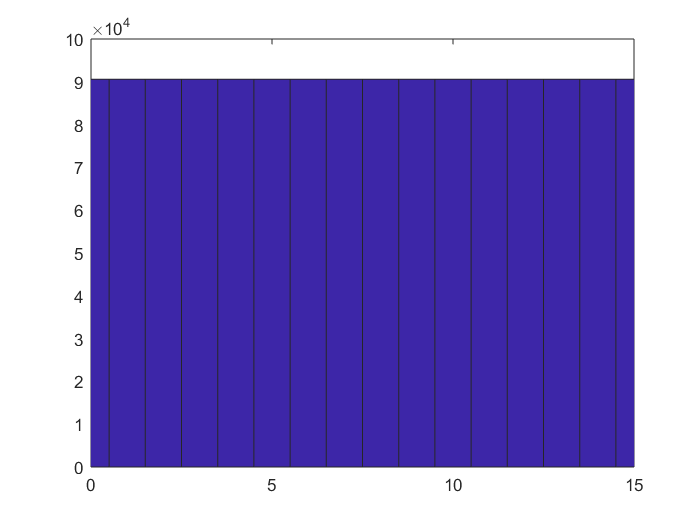

figure;hist(coach_id,0:1:15);xlim([0 15]);

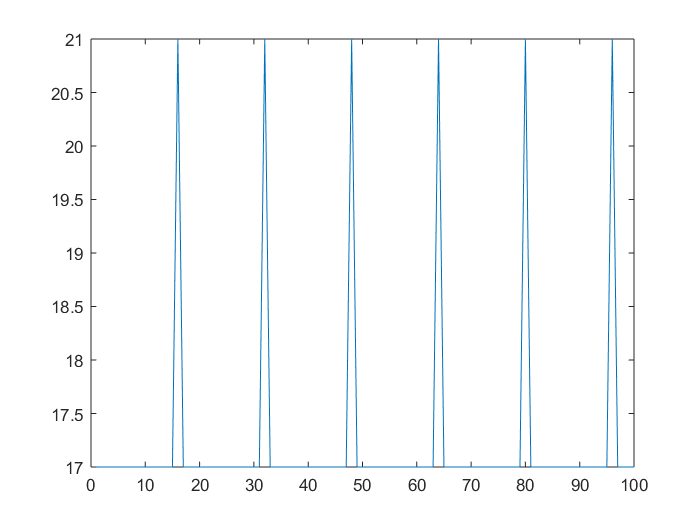

coach_len = diff(coach_end_index);
figure;plot(coach_len(1:100));

sel_coach_id = 15;

c_coach_len = 17;
g_pkg_nums = 2;
% 3(车头标志)+  c_coach_len * sel_coach_id(车厢编号): c_train_len(火车长度) : c_train_len * complet_train_cnt;   
% 寻找所有车厢中编号相同的车厢数据
sel_coach_head_index = 3 +  c_coach_len * sel_coach_id: c_train_len : c_train_len * complet_train_cnt;

sel_coach_data = zeros(complet_train_cnt * c_coach_len,4);

p1 = 1 : c_coach_len : c_coach_len * complet_train_cnt;
for i = 0 : 1 : c_coach_len - 1
    sel_coach_data(p1 + i,:) = train_data(sel_coach_head_index + i,:);
end
p1 = c_coach_len : c_coach_len : c_coach_len * complet_train_cnt;
% 乘客数
pager_cnt = sel_coach_data(p1,2);

index_mask = zeros(complet_train_cnt, c_coach_len);
for i = 1 : 1 : complet_train_cnt
    index_mask(i,1:pager_cnt(i)) = 1;
end
index_mask = index_mask';
index_mask = index_mask(:);

data_index = find(index_mask==1);
data_index = data_index(1:g_pkg_nums:end); % 提取event data的最低字索引
eng = sel_coach_data(data_index,[1,2]);
eng = eng(:,1) + eng(:,2) * 256;
tdc = sel_coach_data(data_index,[3,4]);
tdc = tdc(:,1) + tdc(:,2) * 256;
ch = sel_coach_data(data_index + 1,3) + 1;

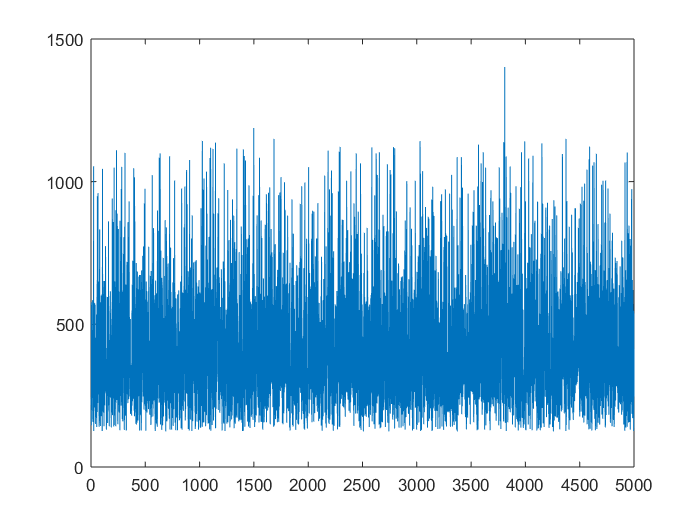

% figure;plot(sel_coach_data);
offset = 0;
figure;plot(eng(offset + 1:offset + 5000));

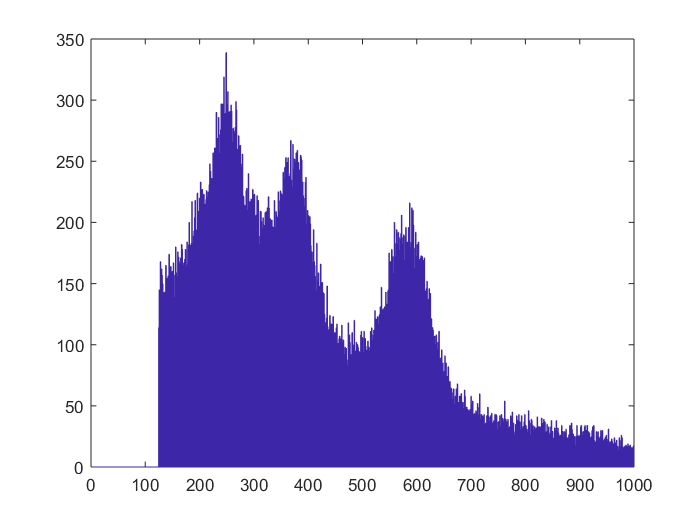

figure;hist(eng, 0:1:2052);xlim([0 1000]);

% %% Plot energy spectrum of a single channel
% ch_seld = 1;
% ch_index = find(ch == ch_seld);
% eng_seld = eng(ch_index);
% figure;hist(eng_seld,0:1:10000);xlim([0 2000]);

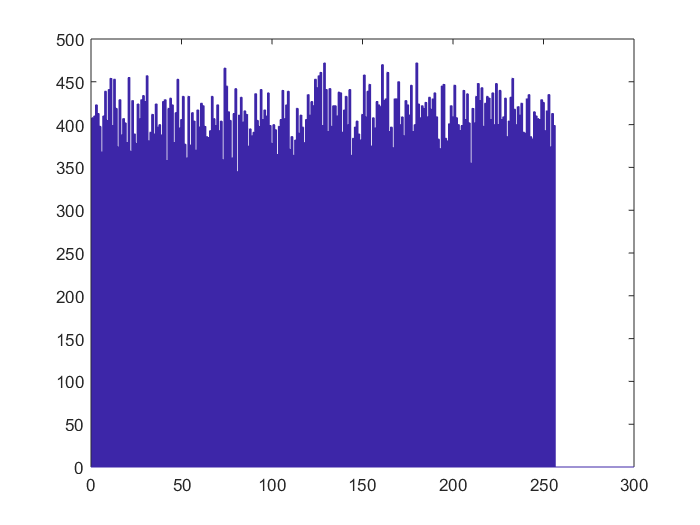

figure;hist(ch,0:1:300);xlim([0 300]);

% figure;
% for ch_seld = 1:100
%     ch_index = find(ch == ch_seld);
%     eng_seld = eng(ch_index);
%     subplot(10, 10, ch_seld - 0); hist(eng_seld,0:1:10000);xlim([0 500]);ylim([0 50]);title(ch_seld);
% end

## 找板间符合--车厢间符合

% clear coach1_index coach1_2_index coach2_index coach2_2_index TDC_coach1 def neighbor_num coin_flag TDC_def maxx maxy maxY hist;
% %分别找第一节和第二节车厢有数据的列车编号
% coach1_index = find(train_data(head_index + 18 , 2)~=0);
% coach1_2_index = find(train_data(head_index + 18 , 2)>2);
% coach2_index = find(train_data(head_index + 35 , 2)~=0);
% coach2_2_index = find(train_data(head_index + 35 , 2)>2);
% 
% %根据第一节车厢寻找相邻4列车内是否有第二节车厢的符合事件
% %第一节车厢的TDC信息
% TDC_coach1 = bitshift(train_data(head_index(coach1_index) + 2,4),8) + train_data(head_index(coach1_index) + 2,3);
% %相邻4车厢车头编号
% % def=[-10 -9 -8 -7 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 7 8 9 10];
% def=[-4 -3 -2 -1 0 1 2 3 4];
% % def=[-2 -1 0 1 2];
% % def=[-1 0 1];
% neighbor_num=[head_index(coach1_index) + def];
% %判断是否有符合0
% coin_flag = ismember(neighbor_num,head_index(coach2_index));
% %找到可能符合的第二车厢的TDC
% for i=1:length(coin_flag(:,1))
%     if coin_flag(i,:)==0
%         TDC_def(i)=65536;
%     else
%         TDC_def(i)=min(abs(bitshift(train_data(neighbor_num(i,coin_flag(i,:)==1) + 19, 4),8) ...
%             + train_data(neighbor_num(i,coin_flag(i,:)==1) ...
%             + 19, 3) - TDC_coach1(i)));
%     end
% end
% TDC_def=TDC_def';
% TDC_def(TDC_def==65536)=[];
% TDC_def(abs(TDC_def)>65536/2) = 65536 - abs(TDC_def(abs(TDC_def)>65536/2));
% hist=hist(abs(TDC_def),0:1:max(TDC_def));
% [maxx maxy]=max(hist);
% maxY=num2str(maxy);
% figure;plot(hist);xlim([0 2*max(TDC_def)]);ylim([0 60000]); text(max(TDC_def),50000,['Δt= ' maxY],'horiz','center','color','r');title('DPch20&HPch0 11th');

## 找通道间符合-单个车厢符合

% clear coach1_index coach1_2_index coach2_index coach2_2_index TDC_coach1 def neighbor_num coin_flag TDC_def ;
% %分别找第一节和第二节车厢有数据的列车编号
% coach1_index = find(train_data(head_index + 18 , 2)~=0);
% coach1_2_index = find(train_data(head_index + 18 , 2)>2);
% coach2_index = find(train_data(head_index + 35 , 2)~=0);
% coach2_2_index = find(train_data(head_index + 35 , 2)>2);
% 
% %根据第一节车厢寻找相邻4列车内是否有第二节车厢的符合事件
% %第一节车厢的TDC信息
% TDC_coach1 = bitshift(train_data(head_index(coach1_index) + 2,4),8) + train_data(head_index(coach1_index) + 2,3);
% %相邻4车厢车头编号
% % def=[-10 -9 -8 -7 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 7 8 9 10];
% def=[-4 -3 -2 -1 0 1 2 3 4];
% % def=[-2 -1 0 1 2];
% % def=[-1 0 1];
% neighbor_num=[head_index(coach1_index) + def];
% %判断是否有符合0
% coin_flag = ismember(neighbor_num,head_index(coach2_index));
% %找到可能符合的第二车厢的TDC
% for i=1:length(coin_flag(:,1))
%     if coin_flag(i,:)==0
%         TDC_def(i)=65536;
%     else
%         TDC_def(i)=min(abs(bitshift(train_data(neighbor_num(i,coin_flag(i,:)==1) + 19, 4),8) ...
%             + train_data(neighbor_num(i,coin_flag(i,:)==1) ...
%             + 19, 3) - TDC_coach1(i)));
%     end
% end
% TDC_def=TDC_def';
% TDC_def(TDC_def==65536)=[];
% TDC_def(abs(TDC_def)>65536/2) = 65536 - abs(TDC_def(abs(TDC_def)>65536/2));
% figure;hist(abs(TDC_def),0:1:max(TDC_def));xlim([0 2*max(TDC_def)]);ylim([0 60000]);